# Filter Design

close all; clear; clc;
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end
clear list_factory index_interpreter default_name i;

SETTINGS.labelFS = 12;
SETTINGS.subtitleFS = 15;
SETTINGS.titleFS = 18;



x = readmatrix("TESTTESTTEST.txt");

The material Absorption coefficients and tilhørende frequencies

materials = [0.02 0.02 0.02 0.03 0.03 0.04 0.05 0.05 0.05 0.05;     %Hard wall
            0.18 0.18 0.12 0.10 0.09 0.08 0.07 0.07 0.07 0.07;      %Wooden Planks
            0.08 0.08 0.24 0.57 0.69 0.71 0.73 0.73 0.73 0.73;      %Carpet
            0.20 0.20 0.15 0.10 0.08 0.04 0.02 0.02 0.02 0.02;      %Plasterboard ceiling
            0.36 0.36 0.26 0.51 0.45 0.62 0.76 0.76 0.76 0.76;      %Curtain
            0.41 0.41 0.67 0.58 0.59 0.68 0.35 0.35 0.35 0.35];      %Perforated chipboard

frequencies = [0 125 250 500 1000 2000 4000 8000 16000 22050];

Area of composite objescts in the room

floorSurface = 7.790*4.130;
RugSurface = 2.60*4.0;
sideWallsSurface = 2.78*7.790;
endWallsSurface = 4.130*2.78;
BigTile = 1.80*0.60;
MediumTile = 0.60*1.20;
smallTile = 0.90*0.60;

Calculation of composite areas of each wall


Front = ((endWallsSurface - (2*BigTile) + smallTile) * materials(1,:) + (2*BigTile + smallTile) * materials(6,:))/endWallsSurface;
Back = materials(1,:);
Right = ((sideWallsSurface - (4*BigTile + smallTile))*materials(1,:) + (smallTile + 4*BigTile) * materials(6,:))/endWallsSurface;
Left = Right;
Floor = ((floorSurface-RugSurface) * materials(2,:) + RugSurface*materials(3,:))/floorSurface;
Ceiling = materials(4,:);

NewMaterial = [
    Front;
    Back;
    Right;
    Left;
    Floor;
    Ceiling
];

Invert values and convert to dB

NewMaterial = 1-NewMaterial;
Walls_dB = 20*log10(NewMaterial);

Init shit

Fs = 44100; % specify the sampling frequency (in Hz)
freq_normal = frequencies/(Fs/2); % normalize the frequencies
f = figure('Position', [10 10 900 300]);
semilogx(frequencies,Walls_dB(1,:), 'LineWidth', 2)

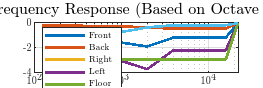

%xlabel('Frequency [Hz]', 'FontSize', SETTINGS.labelFS);
%ylabel('Magnitude [dB]', 'FontSize', SETTINGS.labelFS);
title('Interpolated Filter Frequency Response (Based on Octave Reflection Coefficient)', 'FontSize', SETTINGS.labelFS)
hold on;
grid;
semilogx(frequencies,Walls_dB(2,:), 'LineWidth', 2)
semilogx(frequencies,Walls_dB(3,:), 'LineWidth', 2)
semilogx(frequencies,Walls_dB(4,:), 'LineWidth', 2)
semilogx(frequencies,Walls_dB(5,:), 'LineWidth', 2)
semilogx(frequencies,Walls_dB(6,:), 'LineWidth', 2)
hold off

legend('Front', 'Back', 'Right', 'Left', 'Floor', 'Ceiling', 'Location', 'southwest');
hold off;
exportgraphics(f,'krisErGrim.pdf','Resolution',300);

Init the filter specs

NFront = 300; % Filter order
NBack = 300;
NRightLeft = 300;
NFloor = 300;
NCeiling = 300;

FrontFilter = fir2(NFront, freq_normal, NewMaterial(1,:));
BackFilter = fir2(NBack, freq_normal, NewMaterial(2,:));
RightLeftFilter = fir2(NRightLeft, freq_normal, NewMaterial(3,:));
FloorFilter = fir2(NFloor, freq_normal, NewMaterial(5,:));
CeilingFilter = fir2(NCeiling, freq_normal, NewMaterial(6,:));

rFront = conv(FrontFilter,flip(FrontFilter));
rBack = conv(BackFilter,flip(BackFilter));
rRightLeft = conv(RightLeftFilter, flip(RightLeftFilter));
rFloor = conv(FloorFilter,flip(FloorFilter));
rCeiling = conv(CeilingFilter,flip(CeilingFilter));

FrontMin = firminphase(rFront);
BackMin = firminphase(rBack);
RightLeftMin = firminphase(rRightLeft);
FloorMin = firminphase(rFloor);
CeilingMin = firminphase(rCeiling);

## Front Wall Filter


n = 31;
n1 = 11

n1 = 11

text = readmatrix("TESTTESTTEST.txt")

text =    -1.9184   -0.1311   -0.7686    2.3900    0.0772    0.3756    0.3956   -0.1125   -1.8290    2.0915    0.3591   -0.7943   -0.2273    1.5938    0.1552    0.1786   -0.3377   -1.5250   -0.7094   -0.8666    0.0715    0.1556   -0.1822    0.7310   -0.3476    0.2344   -0.8677   -0.9825   -0.2936    0.8245    0.1941    0.2977   -0.7101   -0.6877    0.5728    0.4452   -1.3260   -1.4999    1.0160   -0.0275   -0.1604    0.3788   -0.1072    0.2128    0.4681   -1.6161    0.0147   -0.0378    0.4038    0.3053


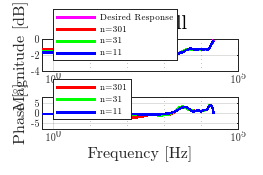


[hFront,wFront] = freqz(FrontMin, 1, Fs);
[hFrontMin30,wFrontMin30] = freqz(FrontMin(1,1:n), 1, Fs);
[hFrontMin10,wFrontMin10] = freqz(FrontMin(1,1:n1), 1, Fs);

f = figure('Position', [10 10 900 600]);
tiledlayout(2,1);
nexttile;
s = semilogx(frequencies,Walls_dB(1,:), 'LineWidth', 2);
s.Color = 'magenta';
grid;
hold on;
s = semilogx(wFront*(22050/pi),20*log10(abs(hFront)), 'LineWidth', 2);
s.Color = 'red';
s = semilogx(wFrontMin30*(22050/pi),20*log10(abs(hFrontMin30)), 'LineWidth', 2);
s.Color = 'green';
s = semilogx(wFrontMin10*(22050/pi),20*log10(abs(hFrontMin10)), 'LineWidth', 2);
s.Color = 'blue';
%xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]', 'FontSize', SETTINGS.labelFS);
ylim([-4 0]);
title('Front Wall', 'FontSize', SETTINGS.subtitleFS)
legend('Desired Response', 'n=301', 'n=31', 'n=11', 'Location', 'southwest');
%xlim([20 -15]);
hold off;

nexttile;
s = semilogx(wFront*(22050/pi), 360/(2*pi)*angle(hFront), 'LineWidth', 2);
s.Color = 'red';
grid;
hold on;
s = semilogx(wFrontMin30*(22050/pi), 360/(2*pi)*angle(hFrontMin30), 'LineWidth', 2);
s.Color = 'green';
s = semilogx(wFrontMin10*(22050/pi), 360/(2*pi)*angle(hFrontMin10), 'LineWidth', 2);
s.Color = 'blue';
xlabel('Frequency [Hz]', 'FontSize', SETTINGS.labelFS);
ylabel('Phase [$^\circ$]', 'FontSize', SETTINGS.labelFS);
ylim([-8 8]);
legend('n=301', 'n=31', 'n=11', 'Location', 'southwest');
hold off;


exportgraphics(f,'frontWallFilterDesign.pdf')

## Back Wall Filter

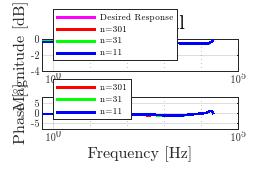

[hBack,wBack] = freqz(BackMin, 1, Fs);
[hBackMin30,wBackMin30] = freqz(BackMin(1,1:n), 1, Fs);
[hBackMin10,wBackMin10] = freqz(BackMin(1,1:n1), 1, Fs);

fb = figure('Position', [10 10 900 600]);
tiledlayout(2,1);
nexttile;
s = semilogx(frequencies,Walls_dB(2,:), 'LineWidth', 2);
s.Color = 'magenta';
grid;
hold on;
s = semilogx(wBack*(22050/pi),20*log10(abs(hBack)), 'LineWidth', 2);
s.Color = 'red';
s = semilogx(wBackMin30*(22050/pi),20*log10(abs(hBackMin30)), 'LineWidth', 2);
s.Color = 'green';
s = semilogx(wBackMin10*(22050/pi),20*log10(abs(hBackMin10)), 'LineWidth', 2);
s.Color = 'blue';
%xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]', 'FontSize', SETTINGS.labelFS);
ylim([-4 0]);
title('Back Wall', 'FontSize', SETTINGS.subtitleFS)
legend('Desired Response', 'n=301', 'n=31', 'n=11', 'Location', 'southwest');
%xlim([20 -15]);
hold off;

nexttile;
s = semilogx(wBack*(22050/pi), 360/(2*pi)*angle(hBack), 'LineWidth', 2);
s.Color = 'red';
grid;
hold on;
s = semilogx(wBackMin30*(22050/pi), 360/(2*pi)*angle(hBackMin30), 'LineWidth', 2);
s.Color = 'green';
s = semilogx(wBackMin10*(22050/pi), 360/(2*pi)*angle(hBackMin10), 'LineWidth', 2);
s.Color = 'blue';
xlabel('Frequency [Hz]', 'FontSize', SETTINGS.labelFS);
ylabel('Phase [$^\circ$]', 'FontSize', SETTINGS.labelFS);
ylim([-8 8]);
legend('n=301', 'n=31', 'n=11', 'Location', 'southwest');
hold off;

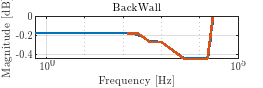


exportgraphics(fb,'backWallFilterDesign.pdf')

figure('Position', [10 10 900 300]);
semilogx(wBack*(22050/pi),20*log10(abs(hBack)), 'LineWidth', 2);
grid;
hold on;
semilogx(frequencies,Walls_dB(2,:), 'LineWidth', 2);
%semilogx(wBackMin*(22050/pi),20*log10(abs(hBackMin)), 'LineWidth', 2);
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('BackWall')
%xlim([20 -15]);
hold off;


l = filter(conv(FrontMin(1,1:n),BackMin(1,1:n)), 1, text);

## Right Left Filter

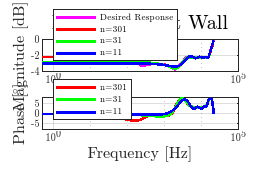

[hRL,wRL] = freqz(RightLeftMin, 1, Fs);
[hRLMin30,wRLMin30] = freqz(RightLeftMin(1,1:n), 1, Fs);
[hRLMin10,wRLMin10] = freqz(RightLeftMin(1,1:n1), 1, Fs);

frl = figure('Position', [10 10 900 600]);
tiledlayout(2,1);
nexttile;
s = semilogx(frequencies,Walls_dB(3,:), 'LineWidth', 2);
s.Color = 'magenta';
grid;
hold on;
s = semilogx(wRL*(22050/pi),20*log10(abs(hRL)), 'LineWidth', 2);
s.Color = 'red';
s = semilogx(wRLMin30*(22050/pi),20*log10(abs(hRLMin30)), 'LineWidth', 2);
s.Color = 'green';
s = semilogx(wRLMin10*(22050/pi),20*log10(abs(hRLMin10)), 'LineWidth', 2);
s.Color = 'blue';
%xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]', 'FontSize', SETTINGS.labelFS);
ylim([-4 0]);
title('Right and Left Wall', 'FontSize', SETTINGS.subtitleFS)
legend('Desired Response', 'n=301', 'n=31', 'n=11', 'Location', 'southwest');
%xlim([20 -15]);
hold off;

nexttile;
s = semilogx(wRL*(22050/pi), 360/(2*pi)*angle(hRL), 'LineWidth', 2);
s.Color = 'red';
grid;
hold on;
s = semilogx(wRLMin30*(22050/pi), 360/(2*pi)*angle(hRLMin30), 'LineWidth', 2);
s.Color = 'green';
s = semilogx(wRLMin10*(22050/pi), 360/(2*pi)*angle(hRLMin10), 'LineWidth', 2);
s.Color = 'blue';
xlabel('Frequency [Hz]', 'FontSize', SETTINGS.labelFS);
ylabel('Phase [$^\circ$]', 'FontSize', SETTINGS.labelFS);
ylim([-8 8]);
legend('n=301', 'n=31', 'n=11', 'Location', 'southwest');
hold off;

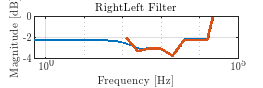


exportgraphics(frl,'rlWallFilterDesign.pdf')


figure('Position', [10 10 900 300]);
semilogx(wRL*(22050/pi),20*log10(abs(hRL)), 'LineWidth', 2);
grid;
hold on;
semilogx(frequencies,Walls_dB(3,:), 'LineWidth', 2);
%semilogx(wRLMin*(22050/pi),20*log10(abs(hRLMin)), 'LineWidth', 2);
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('RightLeft Filter')
%xlim([20 -15]);
hold off;


a = filter(RightLeftMin(1,1:n),1,text);

## Floor Filter

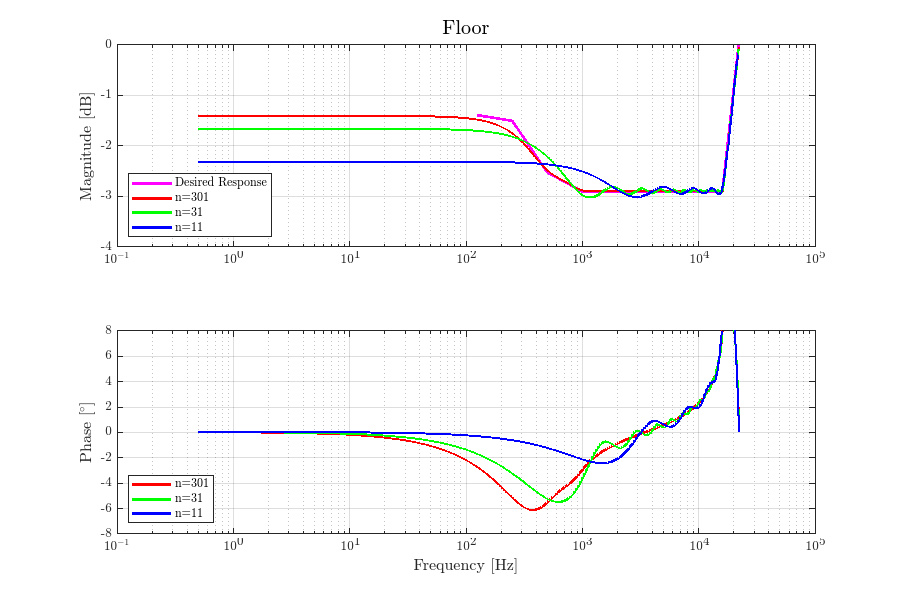

[hFloor,wFloor] = freqz(FloorMin, 1, Fs);
[hFloorMin30,wFloorMin30] = freqz(FloorMin(1,1:n), 1, Fs);
[hFloorMin10,wFloorMin10] = freqz(FloorMin(1,1:n1), 1, Fs);

ff = figure('Position', [10 10 900 600]);
tiledlayout(2,1);
nexttile;
s = semilogx(frequencies,Walls_dB(5,:), 'LineWidth', 2);
s.Color = 'magenta';
grid;
hold on;
s = semilogx(wFloor*(22050/pi),20*log10(abs(hFloor)), 'LineWidth', 2);
s.Color = 'red';
s = semilogx(wFloorMin30*(22050/pi),20*log10(abs(hFloorMin30)), 'LineWidth', 2);
s.Color = 'green';
s = semilogx(wFloorMin10*(22050/pi),20*log10(abs(hFloorMin10)), 'LineWidth', 2);
s.Color = 'blue';
%xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]', 'FontSize', SETTINGS.labelFS);
ylim([-4 0]);
title('Floor', 'FontSize', SETTINGS.subtitleFS)
legend('Desired Response', 'n=301', 'n=31', 'n=11', 'Location', 'southwest');
%xlim([20 -15]);
hold off;

nexttile;
s = semilogx(wFloor*(22050/pi), 360/(2*pi)*angle(hFloor), 'LineWidth', 2);
s.Color = 'red';
grid;
hold on;
s = semilogx(wFloorMin30*(22050/pi), 360/(2*pi)*angle(hFloorMin30), 'LineWidth', 2);
s.Color = 'green';
s = semilogx(wFloorMin10*(22050/pi), 360/(2*pi)*angle(hFloorMin10), 'LineWidth', 2);
s.Color = 'blue';
xlabel('Frequency [Hz]', 'FontSize', SETTINGS.labelFS);
ylabel('Phase [$^\circ$]', 'FontSize', SETTINGS.labelFS);
ylim([-8 8]);
legend('n=301', 'n=31', 'n=11', 'Location', 'southwest');
hold off;


exportgraphics(ff,'floorWallFilterDesign.pdf')


figure('Position', [10 10 900 300]);
semilogx(wFloor*(22050/pi),20*log10(abs(hFloor)), 'LineWidth', 2);
grid;
hold on;
semilogx(frequencies,Walls_dB(5,:), 'LineWidth', 2);
%semilogx(wFloorMin*(22050/pi),20*log10(abs(hFloorMin)), 'LineWidth', 2);
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('Floor')
%xlim([20 -15]);
hold off;

## Ceiling Filter

[hCeiling,wCeiling] = freqz(CeilingMin, 1, Fs);
[hCeilingMin30,wCeilingMin30] = freqz(CeilingMin(1,1:n), 1, Fs);
[hCeilingMin10,wCeilingMin10] = freqz(CeilingMin(1,1:n1), 1, Fs);

fc = figure('Position', [10 10 900 600]);
tiledlayout(2,1);
nexttile;
s = semilogx(frequencies,Walls_dB(6,:), 'LineWidth', 2);
s.Color = 'magenta';
grid;
hold on;
s = semilogx(wCeiling*(22050/pi),20*log10(abs(hCeiling)), 'LineWidth', 2);
s.Color = 'red';
s = semilogx(wCeilingMin30*(22050/pi),20*log10(abs(hCeilingMin30)), 'LineWidth', 2);
s.Color = 'green';
s = semilogx(wCeilingMin10*(22050/pi),20*log10(abs(hCeilingMin10)), 'LineWidth', 2);
s.Color = 'blue';
%xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]', 'FontSize', SETTINGS.labelFS);
ylim([-4 0]);
title('Ceiling', 'FontSize', SETTINGS.subtitleFS)
legend('Desired Response', 'n=301', 'n=31', 'n=11', 'Location', 'southwest');
%xlim([20 -15]);
hold off;

nexttile;
s = semilogx(wCeiling*(22050/pi), 360/(2*pi)*angle(hCeiling), 'LineWidth', 2);
s.Color = 'red';
grid;
hold on;
s = semilogx(wCeilingMin30*(22050/pi), 360/(2*pi)*angle(hCeilingMin30), 'LineWidth', 2);
s.Color = 'green';
s = semilogx(wCeilingMin10*(22050/pi), 360/(2*pi)*angle(hFloorMin10), 'LineWidth', 2);
s.Color = 'blue';
xlabel('Frequency [Hz]', 'FontSize', SETTINGS.labelFS);
ylabel('Phase [$^\circ$]', 'FontSize', SETTINGS.labelFS);
ylim([-8 8]);
legend('n=301', 'n=31', 'n=11', 'Location', 'southwest');
hold off;

exportgraphics(fc,'ceilingWallFilterDesign.pdf')


figure('Position', [10 10 900 300]);
semilogx(wCeiling*(22050/pi),20*log10(abs(hCeiling)), 'LineWidth', 2);
grid;
hold on;
semilogx(frequencies,Walls_dB(6,:), 'LineWidth', 2);
%semilogx(wCeilingMin*(22050/pi),20*log10(abs(hCeilingMin)), 'LineWidth', 2);
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('Ceiling');
%xlim([20 -15]);
hold off;


Check om de er min phase

isminphase(FrontMin(1,1:n))
isminphase(RightLeftMin(1,1:n))
isminphase(BackMin(1,1:n))
isminphase(FloorMin(1,1:n))
isminphase(CeilingMin(1,1:n))


Skriv første refleksions filtre ud.

filterMatrix = [FrontMin(1,1:n1); BackMin(1,1:n1)]
filterMatrix2 = [RightLeftMin(1,1:n); FloorMin(1,1:n); CeilingMin(1,1:n)]; 
writematrix(filterMatrix2, 'Filters.txt')
writematrix(filterMatrix,'Filters2.txt')
%writematrix(BackMin(1,1:n), 'FrontFilter.txt')



q = filter(FrontMin(1,1:n1),1,x);


Convolutede filtre til vægge

FrontBack2ord = conv(FrontMin(1,1:n),BackMin(1,1:n));
%plot(FrontBack2ord);
[hFrontBack,wFrontBack] = freqz(FrontBack2ord(1,1:n), 1, Fs);
%[hCeilingMin,wCeilingMin] = freqz(CeilingMin(1,1:n), 1, Fs);

figure('Position', [10 10 900 300]);
semilogx(wFrontBack*(22050/pi),20*log10(abs(hFrontBack)), 'LineWidth', 2);
grid;
hold on;
semilogx(frequencies,Walls_dB(2,:)+Walls_dB(1,:), 'LineWidth', 2);
%semilogx(wCeilingMin*(22050/pi),20*log10(abs(hCeilingMin)), 'LineWidth', 2);
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('FrontBack/BackFront');
%xlim([20 -15]);
hold off;